clc;
close all;
clear all;

RGB Liste y muestre una figura(s) generada en Matlab de cómo se verían los componentes RGB de la figura 1 en un monitor monocromático de tres canales. Todos los colores tienen máxima intensidad y saturación. Considere el borde en gris medio

figure
colores = {'Negro'; 'Rojo'; 'Amarillo'; 'Verde'; 'Cian'; 'azul'; 'magenta'; 'blanco'};
RGB = { '[0 0 0]'; '[1 0 0]';'[1 1 0]'; '[0 1 0]';'[0 1 1]'; '[0 0 1]';'[1 0 1]'; '[1 1 1]'};

table(colores,RGB)

ans = 8×2 table
      colores           RGB    
    ____________    ___________

    {'negro'   }    {'[0 0 0]'}
    {'rojo'    }    {'[1 0 0]'}
    {'amarillo'}    {'[1 1 0]'}
    {'verde'   }    {'[0 1 0]'}
    {'cian'    }    {'[0 1 1]'}
    {'azul'    }    {'[0 0 1]'}
    {'magenta' }    {'[1 0 1]'}
    {'blanco'  }    {'[1 1 1]'}


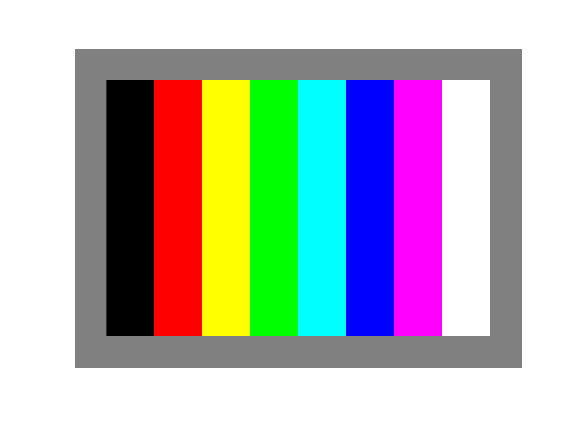

Im = zeros(1000,1400,3);
%grIms
Im(:,:,:)=0.5;
%negro
Im(100:900,100:250,:)=0;
%rojo
Im(100:900,250:400,1)=1;
Im(100:900,250:400,2:3)=0;
%amarImllo
Im(100:900,400:550,1:2)=1;
Im(100:900,400:550,3)=0;
%verde
Im(100:900,550:700,1)=0;
Im(100:900,550:700,2)=1;
Im(100:900,550:700,3)=0;
%cIman
Im(100:900,700:850,1)=0;
Im(100:900,700:850,2:3)=1;
%azul
Im(100:900,850:1000,1:2)=0;
Im(100:900,850:1000,3)=1;
%Magenta
Im(100:900,1000:1150,1)=1;
Im(100:900,1000:1150,2)=0;
Im(100:900,1000:1150,3)=1;
%Blanco
Im(100:900,1150:1300,:)=1;

imshow(Im)

CMY Liste los componentes CMY de la figura 1 como aparecerían en un monitor monocromático de tres canales.

figure
colores = {'negro'; 'rojo'; 'amarillo'; 'verde'; 'cian'; 'azul'; 'magenta'; 'blanco'};
%RGB = { '[0 0 0]'; '[1 0 0]';'[1 1 0]'; '[0 1 0]';'[0 1 1]'; '[0 0 1]';'[1 0 1]'; '[1 1 1]'};
CMY = { '[1 1 1]'; '[0 1 1]';'[0 0 1]'; '[1 0 1]';'[1 0 0]'; '[1 1 0]';'[0 1 0]'; '[0 0 0]'};

table(colores,CMY)

ans = 8×2 table
      colores           CMY    
    ____________    ___________

    {'negro'   }    {'[1 1 1]'}
    {'rojo'    }    {'[0 1 1]'}
    {'amarillo'}    {'[0 0 1]'}
    {'verde'   }    {'[1 0 1]'}
    {'cian'    }    {'[1 0 0]'}
    {'azul'    }    {'[1 1 0]'}
    {'magenta' }    {'[0 1 0]'}
    {'blanco'  }    {'[0 0 0]'}


CMY Describa con sus palabras y muestre la imagen que resulta de pasar los componentes CMY del punto 2 a un monitor RGB. Muestre las figuras generadas en Matlab.

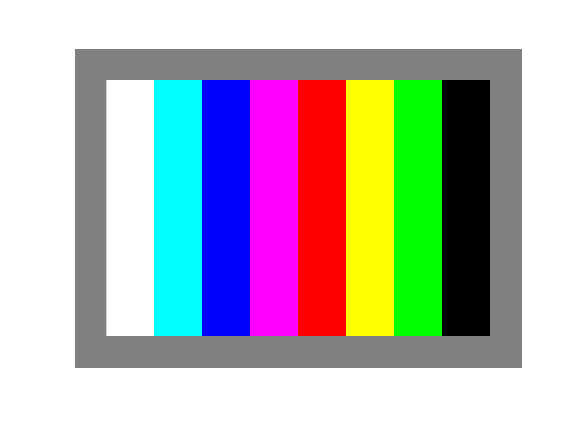

%F=im2double(fondo);
R=Im(:,:,1);
G=Im(:,:,2);
B=Im(:,:,3);
C=1-R;
M=1-G;
Y=1-B;
CMY=cat(3,C,M,Y);

figure
imshow(CMY);

HSI Liste y muestre la imagen que resulta de pasar la imagen de la figura 1 a sus componentes HSI en un monitor monocromático.

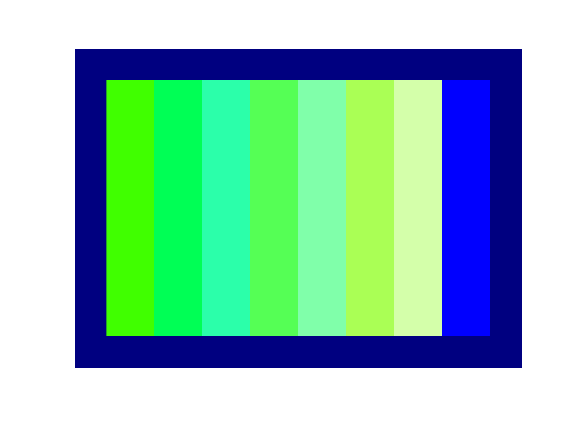

%rgb = im2double(image);
R = Im(:,:,1);
G = Im(:,:,2);
B = Im(:,:,3);

%Angulo
num = 0.5*((R - G)+(R - B));
den = sqrt((R - G).^2 + (R - B).*(G - B));
angulo = acos(num./(den + eps));

% funcion de H
H = angulo;
H(B > G) = 2*pi - H(B > G);
H = H/(2*pi);

% valor minimo de RGB
num = min(min(R,G),B);

% verificacion R+G+B difernte de 0
den = R + G + B;
den(den == 0) = eps;

S = 1 - 3.*num./den;
H(S == 0) = eps;
I = (R + G + B)/3;

% combinacion de cada resultado en la imagen hsi
hsi = cat(3, H, S, I);
imshow(hsi)

hsi(500,25:150:1225,:)

ans = ans(:,:,1) =

    0.0000    0.2500    0.0000    0.1667    0.3333    0.5000    0.6667    0.8333    0.0000


ans(:,:,2) =

     0     1     1     1     1     1     1     1     0


ans(:,:,3) =

    0.5000         0    0.3333    0.6667    0.3333    0.6667    0.3333    0.6667    1.0000


figure
colores = {'Gris'; 'Negro'; 'Rojo'; 'Amarillo'; 'Verde'; 'Cian'; 'Azul'; 'Magenta'; 'Blanco'};
HSI_color = { '[0.00 0.00 0.50]'; '[0.25 1.00 0.00]';'[0.00 1.00 0.33]'; '[0.17 1.00 0.67]';'[0.33 1.00 0.33]'; '[0.50 1.00 0.67]';'[0.66 1.00 0.33]'; '[0.83 1.00 0.67]'; '[0.00 0.00 1.00]'};

table(colores,HSI_color)

ans = 9×2 table
      colores            HSI_color      
    ____________    ____________________

    {'gris'    }    {'[0.00 0.00 0.50]'}
    {'negro'   }    {'[0.25 1.00 0.00]'}
    {'rojo'    }    {'[0.00 1.00 0.33]'}
    {'amarillo'}    {'[0.17 1.00 0.67]'}
    {'verde'   }    {'[0.33 1.00 0.33]'}
    {'cian'    }    {'[0.50 1.00 0.67]'}
    {'azul'    }    {'[0.66 1.00 0.33]'}
    {'magenta' }    {'[0.83 1.00 0.67]'}
    {'blanco'  }    {'[0.00 0.00 1.00]'}


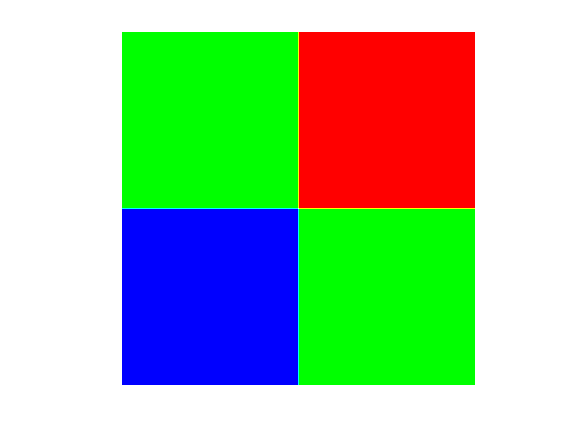

I1=zeros(1000,1000,3);
I1(1:500,1:500,2)=1;
I1(500:1000,500:1000,2)=1;
I1(1:500,500:1000,1)=1;
I1(500:1000,1:500,3)=1;
imshow(I1)

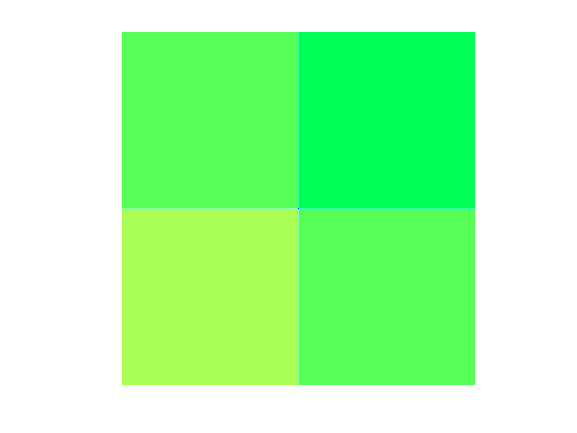

%rgb = im2double(image);
R = I1(:,:,1);
G = I1(:,:,2);
B = I1(:,:,3);
%Angulo
num = 0.5*((R - G)+(R - B));
den = sqrt((R - G).^2 + (R - B).*(G - B));
angulo = acos(num./(den + eps));
% funcion de H
H = angulo;
H(B > G) = 2*pi - H(B > G);
H = H/(2*pi);
% valor minimo de RGB
num = min(min(R,G),B);
% verificacion R+G+B difernte de 0
den = R + G + B;
den(den == 0) = eps;

S = 1 - 3.*num./den;
H(S == 0) = eps;
I = (R + G + B)/3;

% combinacion de cada resultado en la imagen hsi
HSI = cat(3, H, S, I);
imshow(HSI)